# Inverted Pendulum Control

Goal of this exercise is to design pair of robust controllers for simultaneous stabilization of pendulum in upright position and tracking of desired cart position on the track.

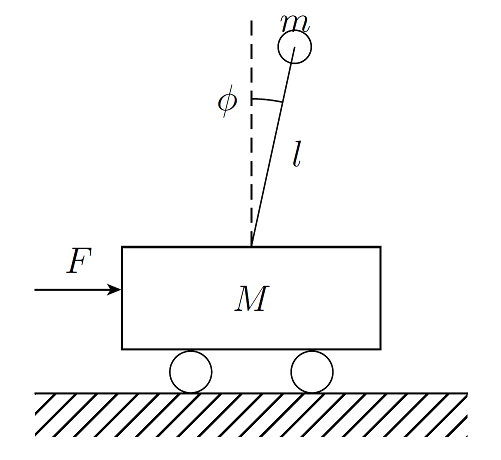

## System definition

Pendulum on cart system is nonlinear system with one stable and one unstable equilibrium points. It can be described by the following set of differential equations:


$$\left(\frac{M}{m}+\mathrm{sin}^2\phi\right)\ddot{x} = -g \mathrm{sin}\phi \mathrm{cos}\phi + l(\dot{\phi})^2 \mathrm{sin}\phi + \frac{F}{m}$$



$$l\left(\frac{M}{m}+\mathrm{sin}^2\phi\right)\ddot{\phi} = (M+m)g\mathrm{sin}\phi - ml\dot{\phi}\mathrm{sin}\phi\mathrm{cos}\phi - F\mathrm{cos}\phi$$


In order to design a robust controller, linearized model of the system is needed. Linearization around the upright equilibrium point results in the following state space system matrices:


$$$A=\left[\matrix{0 & 1 & 0 & 0\cr 0 & 0 & \frac{-mg}{M} & 0 \cr 0& 0 & 0 & 1 \cr 0 & 0 & \frac{(M+m)g}{lM} & 0}\right]$$$



$$$B=\left[\matrix{0 \cr \frac{1}{M}  \cr 0 \cr -\frac{1}{lM} }\right]$$$



$$$C=\left[\matrix{1 & 0 & 0 & 0 \cr 0 & 0 & 1 & 0 }\right]$$$



$$$D=\left[\matrix{0 \cr 0 }\right]$$$


With $x=\lbrack x,\dot{x} ,\phi ,\dot{\phi} \rbrack$, $u=\textrm{Fy}$,$y=\lbrack x,\phi \rbrack^T$ and $l=0\ldotp 305$, $m=0\ldotp 21$, $M=0\ldotp 455$

clear all;
close all;

l = 0.305;
m = 0.21;
M = 0.455;

theta0 = 10; % initial pendulum angle - only for simulink model
g = 9.8;

A = [0 1 0 0;
    0 0 -m*g/M 0;
    0 0 0 1;
    0 0 (M+m)*g/l/M 0];
B = [0; 1/M; 0; -1/M/l];
C = [0 0 1 0];
D = 0;

G = ss(A,B,C,D);
G.InputName = 'F';
G.OutputName = {'angle'};
G.StateName = {'position','velocity','angle','angular velocity'};

## Control structure and controller optimization

Optimization will again be carried out in two steps:

- Synthesis of the stabilizing controller Kstab

- Optimization of the position tracking PD controller Kpol

Controller from the first step is unstructured (full state space) controller designed using hinfsyn function, the second (position) controller is structured (PD) controller optimized using hinfstruct function. Use knowledge gained from previous exercises to define corrent control structures!!!

### **Stabilizing controller synthesis**

- Define (or modify) the plant to have single input (force $F$) and single output (angle$\phi \;$) 

- Define subtraction block as $F=F_2 -F_{1\;} \;$

- Define weights for S and T, where *F*is the input to the $S$ and $\phi \;$input to the $T$

- Construct the feedback according to the following diagram (use connect function):

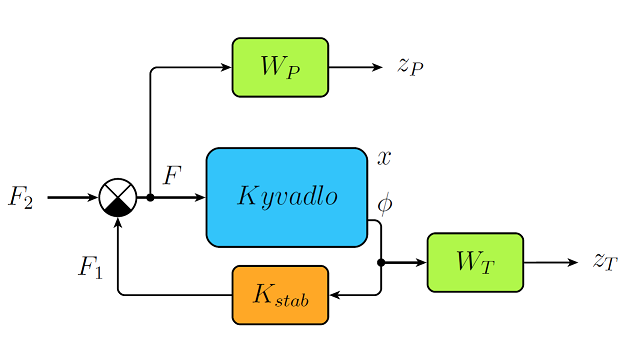

hint: connect will contain plant, Wp, Wt, Sum, with F2 as exogenous input, F1 control input, zp, zt as error (optimized) outputs and angle as measured output (controller Kstab is **not part of the diagram!!!** thats why you need to specify control input and measured output

Sum = sumblk('F = F2-F1');

% sensitivity function weight
As = 1/100;% FILL IN         
M =  2; % FILL IN            
wb = 1;% FILL IN          

Wp = makeweight(1/As,wb, 1/M);% FILL IN
Wp.InputName = 'F'; % FILL IN
Wp.OutputName = 'zp';% FILL IN

% complementary sensitivity function weight
At = 1.01; % FILL IN                         
Mt = 1/1000; % FILL IN                              
wt = 100; % FILL IN 
%(you can try using static weight)

Wt = makeweight(1/At,wt, 1/Mt);% FILL IN
Wt.InputName = 'angle'; % FILL IN
Wt.OutputName = 'zt';% FILL IN

% system interconnection for controller synthesis (with weights)
system = connect(Wt,Wp,G,Sum,{'F1';'F2'},{'zp';'zt';'angle'}); % FILL IN

Controller synthesis using hinfsyn function

nmeas = 1; % number of measurements
ncon = 1; % number of controls

[Kstab,CL,gam] = hinfsyn(system,nmeas,ncon);

Kstab.InputName = 'angle'; % FILL IN
Kstab.OutputName = 'F1';% FILL IN

After the successful optimization using hinfsyn function you can specify simulation diagram (without weights) to see if S and T are under their respective bounds.

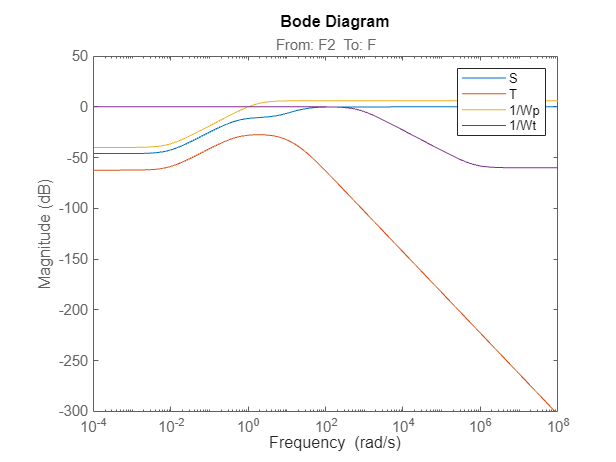

systemS = connect(G,Kstab,Sum,{'F2'},{'F'});% FILL IN
systemT = connect(G,Kstab,Sum,{'F2'},{'angle'});% FILL IN

figure
bodemag(systemS)
hold on
bodemag(systemT)
bodemag(1/Wp)
bodemag(1/Wt)
legend("S","T","1/Wp","1/Wt")

### **Position controller optimization**

- Modify the plant to also include the angle as output

- Define another subtraction block as $e_x =r_{x\;} -x$

- Define (or modify existing) weights for S and T (this time with $e_x \;$as input to **S** and ***x*** as input to **T**)

- Define empty PD controller using the ltiblock.pid function, name its I/O

- Implement the following control structure using the connect function:

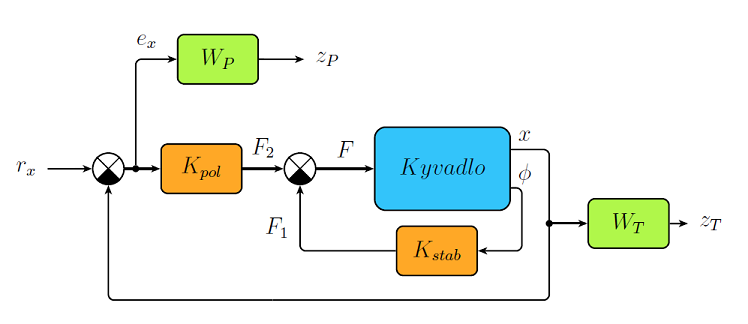

hint: don't forget to include the Kstab controller and "empty" PD controller, this time there will be no control inputs and measured outputs!!! Only inputs and outputs of this diagram are: setpoint $r_x$, optimized outputs$z_P$ and $z_T$.

SumP = sumblk('ex = rx - position');% FILL IN

% add another line to the C matrix - position output
C = [1 0 0 0;
     C];% FILL IN

G = ss(A,B,C,D);
G.InputName = 'F';
G.OutputName = {'position','angle'};
G.StateName = {'position','velocity','angle','angular velocity'};

% sensitivity function weight
Ap = 1/100;       
Mp = 2;            
wbp = 0.1;       

Wp = makeweight(1/Ap,wbp, 1/Mp);% FILL IN
Wp.InputName = 'ex'; % FILL IN
Wp.OutputName = 'zp';% FILL IN

% Not needed
% At = 1.01;                          
% Mt = 1/1000;                              
% wt = 1;
% 
% Wt = makeweight(1/At,wt,1/Mt);
% 
% Wt.InputName = 'position';
% Wt.OutputName = 'zt';

We will be using PD controller for the position. Instead of **hinfsyn** we will use **hinfstruct **to optimize the controller. The hinfstruct function needs "empty" controller block for the synthesis, lets define one using **ltiblock** function:

Kpd = ltiblock.pid('Kpd','pd');  % FILL IN
Kpd.InputName = 'ex';% FILL IN
Kpd.OutputName = 'F2';% FILL IN

The rest is almost the same as for stabilizing controller with one important change - **controller is included in the controller synthesis diagram!!!**

system = connect(Kpd,Wp,Sum,G,Kstab,SumP,{'rx'},{'position'});% FILL IN


rng('default')
opt = hinfstructOptions('Display','final','RandomStart',5);
[sysOpt, gam] = hinfstruct(system,opt);

Final: Failed to enforce closed-loop stability (max Re(s) = 5.7)
Final: Failed to enforce closed-loop stability (max Re(s) = 5.7)
Final: Failed to enforce closed-loop stability (max Re(s) = 5.7)
Final: Failed to enforce closed-loop stability (max Re(s) = 5.7)
Final: Failed to enforce closed-loop stability (max Re(s) = 5.6)
Final: Failed to enforce closed-loop stability (max Re(s) = 5.7)
Failed to stabilize closed-loop system. Try different initial values or increase the number of random starts using "systuneOptions".


Now we need to store the controller and name its I/O:

Kpd = getBlockValue(sysOpt,'Kpd');
Kpd.InputName = 'ex';% FILL IN
Kpd.OutputName = 'F2';% FILL IN

After the successful optimization of position controller you can get its parameters by calling getBlockValue function and simulate the $S$ and $T$.

systemT = connect(G,Kstab,Kpd,Sum,SumP,{'rx'},{'position'});% FILL IN
systemS = connect(G,Kstab,Kpd,Sum,SumP,{'rx'},{'ex'});

figure
bodemag(systemS)
hold on
bodemag(systemT)
bodemag(1/Wp)
bodemag(1/Wt)

## Simulink model

Since the plant is non-linear it would be impractical to use just the simplified state space realization for simulation. You can use the non-linear simulink model provided below in order to see how both controllers work on something that more resembles the real system.